# Matematický model letu rakety s odporem prostředí

Počáteční stav se nastavuje zadáním odchylky (deviation) od pracovního bodu.

Animace průběhů se spouští přes samostatné skripty "animateLinear" a "animateNonlinear". Animace jsou "off-line" - používají předem vypočtená data (structy linearOutput a nonlinearOutput), před spuštěním animace tedy musí být spuštěn tento skript. 

Reguluje se směr rychlosti $\beta$, v animaci je to červená šipka. Černá šipka je hlavní osa rakety, zelená úhel natočení trysky. Pro animaci nelineárního modelu se zobrazují i výslednice sil v X a Y souřadnici - modré šipky.

## Parametry modelu

I_CoM = 1500; % moment setrvacnosti [kg*m^2]
L = 5; % vzdalenost stredu hmotnosti od pohonu [m]
C_DX = 4; % Konstanta odporu prostredi pri pohybu kolmo na hlavni osu rakety [N / (m*s^-2)^2]
C_DY = 0.2; % Konstanta odporu prostredi pri pohybu paralelne s hlavni osou rakety [N / (m*s^-2)^2]
C_M = 12; % konstanta momentoveho odporu prostredi [N*m / rad]
C_Alpha = 1000; % konstanta tlumeni uhlove rychlosti [N*m / (rad/s)^2]
m = 100; % hmotnost [kg]
g = 9.81; % intenzita gravitacniho pole [N*kg^-1]

## Nastavování pracovního bodu a linearizace v pracovním bodě

v_operating = 140;
beta_operating = pi/4;
run("calculations.mlx");

Stavové rovnice


$$x1prime = x_{2}$$

$$x2prime = \begin{array}{l} -\frac{\cos\left(x_{5}\right)\,\left(F_{t}\,\sin\left(u\right)+G\,\sin\left(x_{5}\right)+\cos\left(\sigma_{1}\right)\,\left(4\,{x_{2}}^{2}+4\,{x_{4}}^{2}\right)\right)}{100}-\frac{\sin\left(x_{5}\right)\,\left(F_{t}\,\cos\left(u\right)-G\,\cos\left(x_{5}\right)+\sin\left(\sigma_{1}\right)\,\left(\frac{{x_{2}}^{2}}{5}+\frac{{x_{4}}^{2}}{5}\right)\right)}{100}\\ \mathrm{where}\\ \sigma_{1}=x_{5}-\text{atan2}\left(x_{4},x_{2}\right) \end{array}$$

$$x3prime = x_{4}$$

$$x4prime = \begin{array}{l} \frac{\cos\left(x_{5}\right)\,\left(F_{t}\,\cos\left(u\right)-G\,\cos\left(x_{5}\right)+\sin\left(\sigma_{1}\right)\,\left(\frac{{x_{2}}^{2}}{5}+\frac{{x_{4}}^{2}}{5}\right)\right)}{100}-\frac{\sin\left(x_{5}\right)\,\left(F_{t}\,\sin\left(u\right)+G\,\sin\left(x_{5}\right)+\cos\left(\sigma_{1}\right)\,\left(4\,{x_{2}}^{2}+4\,{x_{4}}^{2}\right)\right)}{100}\\ \mathrm{where}\\ \sigma_{1}=x_{5}-\text{atan2}\left(x_{4},x_{2}\right) \end{array}$$

$$x5prime = x_{6}$$

$$x6prime = -\frac{2\,x_{6}}{3}-\frac{F_{t}\,\sin\left(u\right)}{300}-\frac{\sin\left(x_{5}+\frac{\pi }{2}-\text{atan2}\left(x_{4},x_{2}\right)\right)\,\left(12\,{x_{2}}^{2}+12\,{x_{4}}^{2}\right)}{1500}$$

Pracovní bod


ex_prime = 98.9949

ey_prime = 98.9949

F_T = 4.7382e+03

ePhi = -0.2165

eAlpha = -0.7638

xs =          0   98.9949         0   98.9949   -0.7638         0


A =          0    1.0000         0         0         0         0
         0   -3.2539         0    2.4587 -575.3271         0
         0         0         0    1.0000         0         0
         0    2.5738         0   -2.9086  542.7332         0
         0         0         0         0         0    1.0000
         0   -0.8260         0    0.7575 -156.7633   -0.6667


B =          0
  -26.3832
         0
   39.3571
         0
  -15.4253


C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D =      0
     0
     0
     0
     0
     0


detA = 0

eigVals =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -3.1598 +12.2813i
  -3.1598 -12.2813i
   0.0494 + 0.0000i
  -0.5590 + 0.0000i



operatingPoint = [0, ex_prime, 0, ey_prime, eAlpha, 0]

operatingPoint =          0   98.9949         0   98.9949   -0.7638         0


disp("Gimbaling angle: " + rad2deg(ePhi) + " degrees")

Gimbaling angle: -12.4036 degrees


disp("Thrust: " + F_T + " Newtons")

Thrust: 4738.1959 Newtons


% Pokud je Thrust zaporny nebo GimbalAngle vetsi nez 45 stupnu, problem je ve
% spatne volbe reseni dynamicke rovnovahy ve skriptu "calculations"

## Nastavování počáteční odchylky a výpočet počáteční podmínky 

%deviation = [0, -ex_prime, 0, -ey_prime+40, -eAlpha, 0] %vertikalni start
deviation = [0, -10, 0, 10, -deg2rad(15), 0]

deviation =          0  -10.0000         0   10.0000   -0.2618         0


% Vypocet pocatecni podminky
initialCondition = operatingPoint + deviation

initialCondition =          0   88.9949         0  108.9949   -1.0256         0


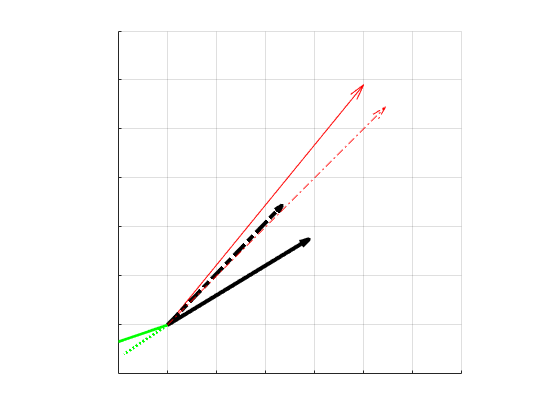


%% Vykresleni pocatecniho stavu(plna) a pracovniho bodu(cerchovana)
figure
hold on
grid on

[xH, yH] = pol2cart(initialCondition(5) + pi/2, 75);
quiver( initialCondition(1), initialCondition(3),...
    xH, yH,...
    'Color', 'Black',...
    'LineWidth', 3)

quiver( initialCondition(1), initialCondition(3),...
    initialCondition(2), initialCondition(4),...
    'Color', 'Red')

phi = initialCondition(5) + ePhi - pi/2;
[xT, yT] = pol2cart(phi, F_T/200);
    quiver( initialCondition(1), initialCondition(3),...
        xT, yT,...
        'Color', 'Green',...
        'LineWidth', 2, ...
        'ShowArrowHead', 'off'); 
    
[xH, yH] = pol2cart(operatingPoint(5) + pi/2, 75);
quiver( operatingPoint(1), operatingPoint(3),...
    xH, yH,...
    'Color', 'Black',...
    'LineWidth', 3,...
    'LineStyle', '-.')

quiver( operatingPoint(1), operatingPoint(3),...
    operatingPoint(2), operatingPoint(4),...
    'Color', 'Red',...
    'LineStyle', '-.')

phi = operatingPoint(5) + ePhi - pi/2;
[xT, yT] = pol2cart(phi, F_T/200);
    quiver( operatingPoint(1), operatingPoint(3),...
        xT, yT,...
        'Color', 'Green',...
        'LineWidth', 2, ...
        'ShowArrowHead', 'off',...
        'LineStyle', ':'); 
    

axis equal
xlim([-20, 120])
ylim([-20, 120])
set(gca,'xticklabel',[])
set(gca,'yticklabel',{[]})

## Nastavení numerické metody a simulace

SimulationTime = 60

SimulationTime = 60

rtol = 1e-4

rtol = 1.0000e-04

maxstep = 0.01

maxstep = 0.0100


nonlinearOutput = sim("nonlinearModel.slx")

No system or file called 'nonlinearModel.slx' found.

linearOutput = sim("linearModel.slx")
nonlinearBus = Simulink.Bus.createObject(nonlinearOutput.nonlinear)
linearBus = Simulink.Bus.createObject(linearOutput.linear)
comparedModels = sim("compareModels.slx")

## Vykreslení regulované veličiny $\beta$ a akční veličiny $\varphi$

f1 = figure;
subplot(211);
hold on
grid on
plot(comparedModels.betaNonlinear, "LineWidth", 1)
plot(comparedModels.betaLinear,"LineWidth", 1)
yline(beta_operating, '-.', "LineWidth", 1.5)

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0.7854
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-.'
        LineWidth: 1.5000
            Label: ''
      DisplayName: ''

  Show all properties


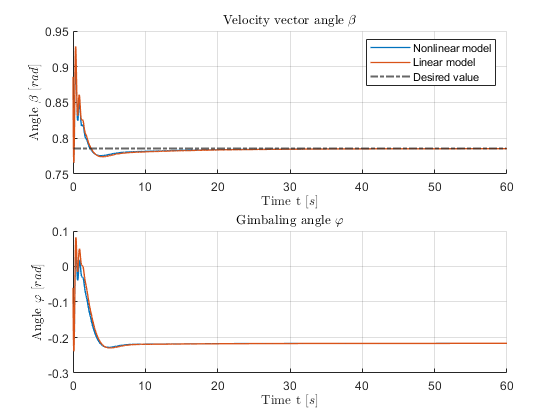

legend("Nonlinear model", "Linear model", "Desired value")
    xlabel('Time t [$s$]','interpreter','latex')
 ylabel('Angle $\beta$ [$rad$]', 'Interpreter', 'Latex')
  title('Velocity vector angle $\beta$', 'Interpreter', 'Latex')
subplot(212);
hold on
grid on
plot(comparedModels.phiNonlinear, "LineWidth", 1)
plot(comparedModels.phiLinear, "LineWidth", 1)
 xlabel('Time t [$s$]', 'Interpreter', 'Latex')
 ylabel('Angle $\varphi$ [$rad$]', 'Interpreter', 'Latex')
 title('Gimbaling angle $\varphi$', 'Interpreter','latex');

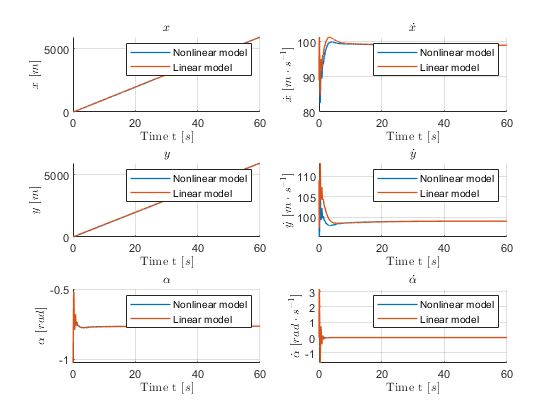

 
f2 = figure;
subplot(321);
hold on
grid on
plot(nonlinearOutput.nonlinear.x, "LineWidth", 1)
plot(linearOutput.linear.x,"LineWidth", 1)
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$x$ [$m$]', 'Interpreter', 'Latex')
  title('$x$', 'Interpreter', 'Latex')
subplot(322);
hold on
grid on
plot(nonlinearOutput.nonlinear.xPrime, "LineWidth", 1)
plot(linearOutput.linear.xPrime,"LineWidth", 1)
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{x}$ [$m\cdot s^{-1}$]', 'Interpreter', 'Latex')
  title('$\dot{x}$', 'Interpreter', 'Latex')
  subplot(323);
hold on
grid on
plot(nonlinearOutput.nonlinear.y, "LineWidth", 1)
plot(linearOutput.linear.y,"LineWidth", 1)
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$y$ [$m$]', 'Interpreter', 'Latex')
  title('$y$', 'Interpreter', 'Latex')
  subplot(324);
hold on
grid on
plot(nonlinearOutput.nonlinear.yPrime, "LineWidth", 1)
plot(linearOutput.linear.yPrime,"LineWidth", 1)
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{y}$ [$m\cdot s^{-1}$]', 'Interpreter', 'Latex')
  title('$\dot{y}$', 'Interpreter', 'Latex')
  subplot(325);
hold on
grid on
plot(nonlinearOutput.nonlinear.alpha, "LineWidth", 1)
plot(linearOutput.linear.alpha,"LineWidth", 1)
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\alpha$ [$rad$]', 'Interpreter', 'Latex')
  title('$\alpha$', 'Interpreter', 'Latex')
  subplot(326);
hold on
grid on
plot(nonlinearOutput.nonlinear.alphaPrime, "LineWidth", 1)
plot(linearOutput.linear.alphaPrime,"LineWidth", 1)
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{\alpha}$ [$rad\cdot s^{-1}$]', 'Interpreter', 'Latex')
  title('$\dot{\alpha}$', 'Interpreter', 'Latex')